## Computational Methods in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Stability of Runge-Kutta Methods

On successful completion of this page readers will be able to:

- Understand the concept of local and global truncation errors and what it means for a method to be considered stable.

- Determine the stability function of explicit and implicit Runge-Kutta method.

- Plot the region of absolute stability.

- Determine whether an implicit Runge-Kutta method is A-stable or not.

The derivation of a numerical method to solve an ODE involves omitting the higher-order terms from the Taylor series known as **truncating** the [Taylor series](https://en.wikipedia.org/wiki/Taylor_series). In doing this we introduce an errors which at each step of the method and it is important to be able to analyse the extent to which these errors affect the numerical solutions. In the majority of cases the exact solution of an ODE is unknown (if it was known we would not need to use a numerical method to solve it) so we cannot determine the values of the errors but we can examine their behaviour through each step of the method.

To do this it is necessary to introduce terminology used to describe the [truncation errors](https://en.wikipedia.org/wiki/Truncation_error_(numerical_integration)).

#### **Definition (local truncation error)**

Let $y_n$ be a numerical approximation of the exact solution $\bar{y}_n$ for some step $n$ of a method then the **local truncation error** is


$$\tau_n = y_n - \bar{y}_n,$$


#### Definition (global truncation error)

The **global truncation error** is the accumulation of the local truncation errors upto the current step


$$E_n = \sum_{i=0}^n \tau_i.$$


If $|\tau_{i+1} - \tau_i|>1$ (i.e., the local truncation errors grow from one step to the next) then $E_n\to \infty$ as $n$ gets large and the method is said to be **unstable** and unusable. So for a method to be considered **stable** we need the the growth in the local truncation errors to remain bounded which leads to the definition of numerical stability.

#### Definition (stability)

If $\tau_n$ is the local truncation error of a numerical method for solving a differential equation then the method is considered **stable** if


$$|\tau_{n+1} - \tau_n|\leq 1,$$


for all steps of the method.

Since the Taylor series truncation error $O(h^n)$ is some function of the step length $h$, as $h$ increases then so does the truncation error and the more likely a method is to be unstable. 

#### Example 1

Consider the [Euler method](https://en.wikipedia.org/wiki/Euler_method) when applied to solve the ODE $y'=-2.3y$ over the domain $t\in [0, 5]$ with an intial condition $y(0)=1$. This ODE has the exact solution $y=e^{-2.3t}$. The code below compares the Euler method solutions using two steps lengths of $h = 0.7$ and $h=1$ to the exact solution.

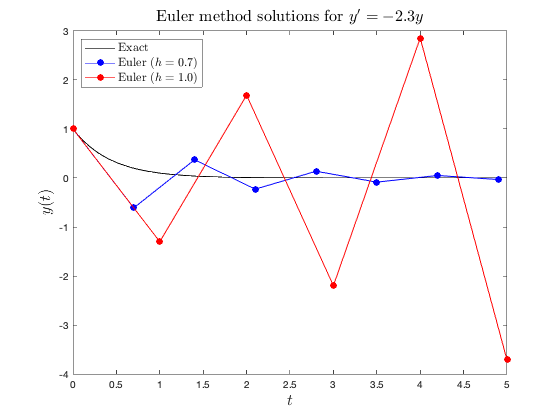

clear

% Define ODE function
f = @(t, y) -2.3 .* y;

% Define exact solution 
exact_sol = @(t) exp(-2.3 .* t);

% Define IVP parameters
tspan = [ 0, 5 ];
y0 = 1;
h1 = 0.7;
h2 = 1.0;

% Solve IVP using the Euler method
[t1, y1] = euler(f, tspan, y0, h1);
[t2, y2] = euler(f, tspan, y0, h2);

% Plot solution
t3 = linspace(tspan(2), tspan(1), 100);
plot(t3, exact_sol(t3), 'k-')
hold on
plot(t1, y1, 'bo-', 'MarkerFaceColor', 'b')
plot(t2, y2, 'ro-', 'MarkerFaceColor', 'r')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Euler method solutions for $y'=-2.3y$", 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'Euler ($h=0.7$)', 'Euler ($h=1.0$)');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that the solution using $h=0.7$ remains stable whereas the solution using $h=1.0$ is diverging and unstable.

## Stability Functions

To examine the behaviour of the local trunction errors as we step through a method we use the test ODE $y'=\lambda y$. As the values of $y_{n+1}$ are updated using the values of $y_n$ so are the values of $\tau_{n+1}$ using $\tau_n$ by the same method. This allows us to define a **stability function** for a method.

#### Definition (stability function)

The **stability function** of a method, $R(z)$ is the rate of growth over a single step of the method when applied to calculate the solution of an ODE of the form $y'=\lambda y$ where $z=h\lambda$ and $h$ is the step size, i.e.,


$$y_{n+1} = R(z) y_n.$$


#### Example 2

Determine the stability function for the Euler method.

If the Euler method is used to solve and ODE of the form$y'=\lambda y$ then the solution will be updated over one step using


$$y_{n+1} = y_n + hf(t_n, y_n),$$


then the local truncation errors will also update in the same step by


$$\tau_{n+1} = \tau_n + h(t_n, \tau_n).$$


Applying the Euler method to the test ODE we have


$$y_{n+1} = y_n + h\lambda y_n.$$


Let $z=h\lambda$ then 


$$y_{n+1} = y_n + zy_n \\ \qquad \! \! =(1 + z)y_n.$$


So the stability function of the Euler method is $R(z) = 1+z$. 

### Absolute stability

We have seen that a necessary condition for stability of a method is that the local truncation errors must not grow from one step to the next. A method satisfying this basic condition is considered to be **absolutely stable**. Since the stability function $R(z)$ is expressed using $z=h\lambda$ then a method may be stable for some value of $z$ and unstable for others. This provides the definition for absolute stability.

#### Definition (absolute stability)

A method is considered to be **absolutely stable** if $|R(z)\leq 1|$ for $z\in \mathbb{C}$.

Of course we require our methods to be stable so it is useful to know for what values of 𝑧z we have a stable method. This gives the definition of the **region of absolute stability**.

#### Definition (region of absolute stability)

The **region of absolute stability** is the set of $z\in \mathbb{C}$ for which a method is absolutely stable


$$\text{region of absolute stability} = \{ z:z\in \mathbb{C}, |R(z)| \leq 1\}.$$


#### Example 3

The stability function for the Euler method is $R(z)= 1+z$. The code below generates a set of points in the complex plane $z=x+iy$ and plots the contour where $|R(z)|=1$ which represents the boundary of the stability region of the Euler method.

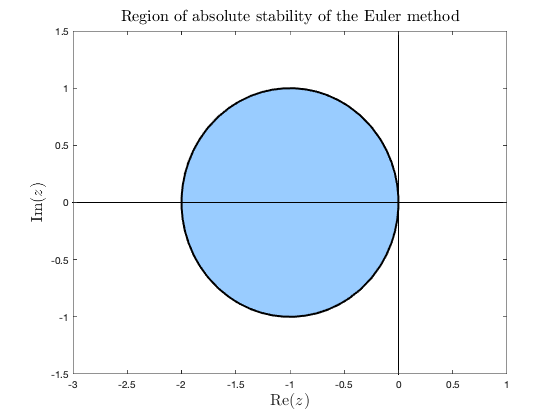

clear 

% Generate z values
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Define the stability function for the euler method
R = 1 + Z;

% Plot the region of absolute stability
contourf(X, Y, abs(R), [0 1], 'linewidth', 2)
hold on
plot([ -10, 10 ], [ 0, 0 ], 'k-')
plot([ 0, 0 ], [ -10, 10 ], 'k-')
hold off

xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
title('Region of absolute stability of the Euler method', ...
    'FontSize', 16, 'Interpreter', 'latex')
axis([ -3, 1, -1.5, 1.5 ])
colormap([ 153, 204, 255 ; 255, 255, 255 ] / 255)

The Euler method for solving $y'=\lambda y$ will be stable for point $z$ that lies within the shaded region.

### Interval of absolute stability

The choice of step length used in a method will depend on accuracy requirements, computational resources available and of course stability. It is often necessary to use as large a value of the step length as possible permitted by the stability requirements to minimise the computational effort required to solve an ODE. The range values of the step length that can be chosen is governed by the stability region and provides use with the following definition.

#### Definition (interval of absolute stability)

The range of real values that the step length $h$ of a method can take that ensures a method remains absolutely stable is known as the **interval of absolute stability**

The region of absolute stability for the Euler method plotted above shows that the interval of absolute stability is


$$z\in [-2, 0],$$


i.e., the real part of the region of absolute stability.

Since $z=h\lambda$ then


$$h\in \left[ -\frac{2}{\lambda} , 0 \right],$$


so we have the condition


$$h \leq -\frac{2}{\lambda}.$$


#### Example 4

The step length for the Euler method when used to solve the ODE $y'=-2.3y$ must satisfy


$$h\leq \frac{2}{2.3} \approx 0.8696.$$


This is why in example 1 the solution using $h=0.7$ was stable since $0.7 < 0.8696$ and the solution using $h=1.0$ was unstable since $1>0.8696$.

## Stability function of a Runge-Kutta method

The general form of a Runge-Kutta method is


$$y_{n+1} = y_n + h \sum_{i=1}^s b_ik_i, \\ 
\quad k_i = f(t_n+c_ih, y_n + h\sum_{j=1}^s a_{ij}k_k).$$


Let $Y_i=y_n + h\sum_{j=1}^s a_{ij}k_j$ and applying the method to the test ODE $y'=\lambda y$ the method becomes


$$y_{n+1} = y_n + h\lambda \sum_{i=1}^s b_i Y_i, \qquad \qquad (1) \\
\qquad Y_i = y_n + h\lambda \sum_{j=1}^s a_{ij}Y_j.$$


Let $z = h\lambda$ and expanding out the summatrions in the stage values gives


$$Y_1 = y_n + z(a_{11} Y_1 + a_{12} Y_2 + \cdots + a_{1s}Y_s), \\
Y_2 = y_n + z(a_{21} Y_1 + a_{22} Y_2 + \cdots + a_{2s}Y_s), \\
\vdots \\
Y_s = y_n + z(a_{s1} Y_1 + a_{s2} Y_2 + \cdots + a_{ss}Y_s).$$


Let $Y = (Y_1, Y_2, \ldots , Y_s)^T$ and $\mathbf{e} = (1, 1, \ldots, 1)^T$ then we can write the stage values in vector form as


$$Y = \mathbf{e}y_n + z A \cdot Y. \qquad \qquad (2)$$


Substituting $\displaystyle\sum_{i=1}^s b_iY_i = \mathbf{b}^T \cdot Y$ into equation (1) gives the vector form of a Runge-Kutta method for solving the test ODE


$$y_{n+1} =y_n + z \mathbf{b}^T \cdot Y. \qquad \qquad (3)$$


### Stability function of an explicit Runge-Kutta method

Rearranging equation (2) we have


$$Y = (I - zA)^{-1} \cdot \mathbf{e}y_n,$$


and substituting into equation (3) gives


$$y_{n+1} = y_n + z \mathbf{b}^T \cdot (I - zA)^{-1} \cdot \mathbf{e}y_n \\ \qquad \!\! = (1 + z\mathbf{b}^T \cdot (I - zA)^{-1} \cdot \mathbf{e})y_n,$$


so the stability function is


$$R(z) = 1 + z \mathbf{b}^T \cdot (I - zA)^{-1}\cdot \mathbf{e}.$$


Using the geometric series of matrices


$$(I - zA)^{-1} = \sum_{k=0}^\infty (zA)^k,$$


the stabilty function can be written as the infinite series


$$R(z) = 1 + \left(\mathbf{b}^T \cdot \sum_{k=0}^\infty A^k \cdot \mathbf{e}\right) z^{k+1}. \qquad \qquad (4)$$


Since the solution to the test ODE is $y=e^{\lambda t}$, over one step of an Explicit Runge-Kutta (ERK) method we would expect the local truncation errors to change at a rate of $e^z$. The series expansion of $e^z$ is


$$e^z = \sum_{k=0}^\infty \frac{1}{k!} z^k = 1 + z + \frac{1}{2}z^2 + \frac{1}{6}z^3 + \frac{1}{24}z^4 + \cdots \qquad \qquad (5)$$


Comparing the coefficients of $z^k$ in equations (4) and (5) we have


$$\frac{1}{k!} =\mathbf{b}^T \cdot A^{k-1} \cdot \mathbf{e},$$


which must be satisfied up to the  $k$th term for an order $k$ ERK method to be stable.

#### Example 5

Determine the stability function for the following Runge-Kutta method and hences find its order.


$$\begin{array}{c|cccc}
    0 & \\
    \frac{1}{2} & \frac{1}{2} \\
    \frac{3}{4} & 0 & \frac{3}{4} \\
    1 & \frac{2}{9} & \frac{1}{3} & \frac{4}{9} \\
    & \frac{7}{24} & \frac{1}{4} & \frac{1}{3} & \frac{1}{8}
    \end{array}$$


The code below calculates the coefficients and outputs the stability function $R(z)$ for this ERK method.

clear

% Define ERK method
A = [ 0, 0, 0, 0 ; 
      1/2, 0, 0, 0 ; 
      0, 3/4, 0, 0 ; 
      2/9, 1/3, 4/9, 0 ];
b = [ 7/24 ; 1/4 ; 1/3 ; 1/8 ];
c = [ 0 ; 1/2 ; 3/4 ; 1 ];
s = length(b);
e = ones(s, 1);

% Determine stability function
R = 'R(z) = 1';
for k = 1 : s
    coeff = b' * A^(k-1) * e;
    R = [ R, sprintf(' + %s z^%1i', strtrim(rats(coeff)), k) ];
end
fprintf(R)

R(z) = 1 + 1 z^1 + 1/2 z^2 + 3/16 z^3 + 1/48 z^4

So the stability function is


$$R(z) = 1 + z + \frac{1}{2}z^2 + \frac{3}{16} z^3 + \frac{1}{48} z^4,$$


which agrees to the series expansion of $e^z$ up to and including the $z^2$ term. Therefore this ERK method is of order 2.

#### Example 6

The code below calculates the stability functions of order 1, 2, 3 and 4 ERK methods and plots their regions of absolute stability.

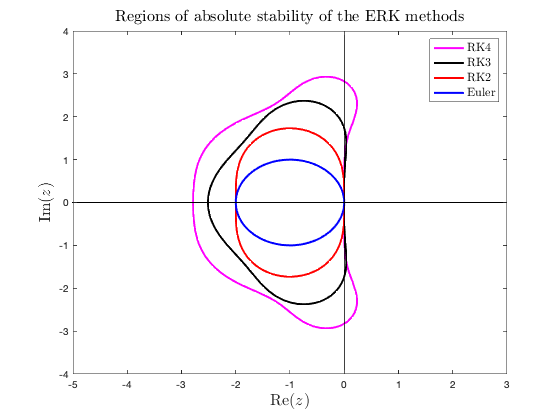

clear

% Generate z values
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Define the stability functions for the ERK methods
R1 = 1 + Z;
R2 = R1 + 1/2 * Z.^2;
R3 = R2 + Z.^3 / 6;
R4 = R3 + Z.^4 / 24;

% Plot the region of absolute stability
contour(X, Y, abs(R4), [1, 1], 'm-', 'linewidth', 2)
hold on
contour(X, Y, abs(R3), [1, 1], 'k-', 'linewidth', 2)
contour(X, Y, abs(R2), [1, 1], 'r-', 'linewidth', 2)
contour(X, Y, abs(R1), [1, 1], 'b-', 'linewidth', 2)
plot([ -10, 10 ], [ 0, 0 ], 'k-')
plot([ 0, 0 ], [ -10, 10 ], 'k-')
hold off

axis([-5, 3, -4, 4])
xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
title('Regions of absolute stability of the ERK methods', ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('RK4', 'RK3', 'RK2', 'Euler');
set(legend, 'Fontsize', 12, 'Interpreter', 'latex')

### Stability functions of implicit methods

The simplest implicit method for solving ODEs is the [Backwards Euler](https://en.wikipedia.org/wiki/Backward_Euler_method) method (also known as the implicit Euler method) which is


$$y_{n+1} = y_n + hf(t_n+h, y_{n+1}).$$


Applying this to solve the test ODE $y'=\lambda y$ and rearranging gives


$$\qquad \quad \,\,\,y_{n+1} = y_n + h\lambda y_{n+1} \\
(1 - h\lambda)y_{n+1} = y_n \\
\qquad \quad \,\,\,y_{n+1} = \frac{1}{1 - h\lambda}y_n,$$


therefore the stability function for the backwards Euler method is $R(z) = \frac{1}{1-z}$. Stability functions for implicit methods take the form of a rational fraction


$$R(z) = \frac{P(z)}{Q(z)}.$$


#### Example 7

The code below plots the region of absolute stability of the backwards Euler method.

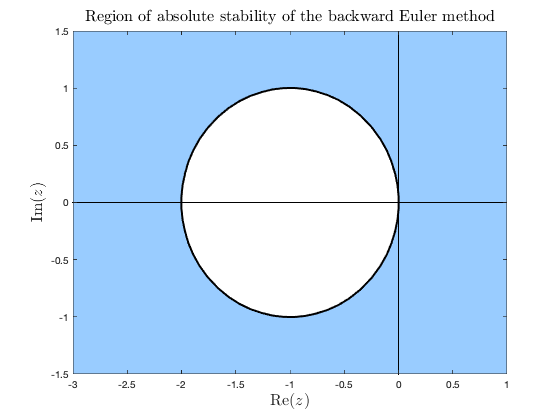

clear 

% Generate z values
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Define the stability function for the backwards Euler method
R = 1 ./ (1 + Z);

% Plot the region of absolute stability
contourf(X, Y, abs(R), [0 1], 'linewidth', 2)
hold on
plot([ -10, 10 ], [ 0, 0 ], 'k-')
plot([ 0, 0 ], [ -10, 10 ], 'k-')
hold off

xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
title('Region of absolute stability of the backward Euler method', ...
    'FontSize', 16, 'Interpreter', 'latex')
axis([ -3, 1, -1.5, 1.5 ])
colormap([ 153, 204, 255 ; 255, 255, 255 ] / 255)

Here the region of absolute stability includes all of the complex plane with the exception of the unshaded region shown here.

### Stability functions for an implicit Runge-Kutta method

To determine the stability function for an Implicit Runge-Kutta (IRK) method we use equations (3) and (2)


$$y_{n+1} = y_n + z \mathbf{b}^T \cdot Y, \\ 
\quad Y = \mathbf{e}y_n + z A \cdot Y.$$


Transposing these equations so that the terms not involving $y_n$ to the left-hand side gives


$$y_{n+1} - z\mathbf{b}^T \cdot Y = y_n \\ 
\quad \!(I - zA)\cdot Y = \mathbf{e}y_n,$$


which can be written as the matrix equation


$$\pmatrix{ 1 & -zb_1 & -zb_2 & \cdots & -zb_s \cr
    0 & 1 - za_{11} & -za_{12} & \cdots & -za_{1s} \cr
    0 & -za_{21} & 1 - za_{22} & \cdots & -za_{2s} \cr
    0 & \vdots & \vdots & \ddots & \vdots  \cr
    0 & -za_{s1} & -za_{s2} & \cdots & 1-za_{ss}
    }
\pmatrix{ y_{n+1} \cr Y_1 \cr Y_2 \cr \vdots \cr Y_s } = 
\pmatrix{ y_n \cr y_n \cr \vdots \cr y_n \cr y_n}.$$


Using [Cramer's rule](https://en.wikipedia.org/wiki/Cramer%27s_rule) to solve this system for $y_{n+1}$ we have


$$y_{n+1} = \frac{\det
\pmatrix{ y_n & -zb_1 & -zb_2 & \cdots & -zb_s \cr
    y_n & 1 - za_{11} & -za_{12} & \cdots & -za_{1s} \cr
    y_n & -za_{21} & 1 - za_{22} & \cdots & -za_{2s} \cr
    y_n & \vdots & \vdots & \ddots & \vdots  \cr
    y_m & -za_{s1} & -za_{s2} & \cdots & 1-za_{ss}
    }}{\det(I - zA)}.$$


Performing a row operation of subtracting the first row of matrix in the numerator from the other rows gives


$$y_{n+1} = \frac{\det
\pmatrix{ y_n & -zb_1 & -zb_2 & \cdots & -zb_s \cr
    0 & 1 - za_{11} + zb_1 & -za_{12} + zb_2 & \cdots & -za_{1s} + zb_s \cr
    0 & -za_{21} + zb_1 & 1 - za_{22} + zb_2 & \cdots & -za_{2s} + zb_s \cr
    0 & \vdots & \vdots & \ddots & \vdots  \cr
    0 & -za_{s1} + zb_1 & -za_{s2} + zb_2 & \cdots & 1-za_{ss} + zb_s
    }}{\det(I - zA)} \cr
    &= \frac{y_n\det(I - z\,(A - \mathbf{e}\cdot \mathbf{b}^T))}{\det(I - z\,A)},$$


where $\mathbf{e}\cdot \mathbf{b}^T$ is a diagonal matrix with the elements of $\mathbf{b}$ on the main diagonal. Therefore the stability function of an Implicit Runge-Kutta (IRK) method can be written as 


$$ R(z) = \frac{\det(I - z\,(A - \mathbf{e}\cdot \mathbf{b}^T))}{\det(I - z\,A)}. \qquad \qquad (6)$$


## A-stability

As we saw in the plot of the region of absolute stability of the backwards Euler method, implicit methods have a much greater region than explicit methods and are very useful for solving stiff ODEs where the stabilty constraints placed on an explcit method means the step length ℎh is too small to be of practical use. A desirable property of some implicit methods is that there is no limit placed on the value of ℎh for which will result in an unstable method, this is known as .

#### Definition (A-stability)

A method is said to be **A-stable** if its region of absolute stabilty satisfies


$$\{z:z \in \mathbb{C}^-, R(z)\leq 1 \}$$


i.e., the method is stable for all points in the left-hand side of the complex plane.

#### Theorem

Given an implicit Runge-Kutta method with a stability function of the form


$$R(z) = \frac{P(z)}{Q(z)},$$


and define a polynomial function


$$E(y) = Q(iy)Q(-iy) - P(iy)P(-iy),$$


then the method is A-stable if and only if the following are satisfied

- All roots of $Q(z)$ have positive real parts;

- $E(y)\geq 0$ for all $y\in \mathbb{R}$.

#### Example 8

Determine the stability function of the following IRK and determine whether it is A-stable or not


$$   \begin{array}{c|cc}
        \frac{1}{3} & \frac{5}{12} & -\frac{1}{12} \\
        1 & \frac{3}{4} & \frac{1}{4} \\
        & \frac{3}{4} & \frac{1}{4}
    \end{array}$$


clear

% Define ERK method
A = [ 5/12 , -1/12
      3/4, 1/4 ];
b = [ 3/4 , 0 ;
      0 , 1/4 ];
I = eye(size(b));

% Calculate P(z) and Q(z) polynomials
syms z
P = det(I - z * (A - b));
Q = det(I - z * A);

% Calculate roots of Q
Qroot = solve(Q == 0);

% Calculate E(y)
syms y
Pp = det(I + 1i * y * (A - b));
Pm = det(I - 1i * y * (A - b));
Qp = det(I + 1i * y * A);
Qm = det(I - 1i * y * A);
E = expand(Qp * Qm - Pp * Pm);

% Output P(z), Q(z), roots of Q(z) and E(y)
for i = 1 : 1
    fprintf('P(z) = %s\nQ(z) = %s', P, Q)
    fprintf('The roots of Q are %s and %s', Qroot(1), Qroot(2))
    fprintf('E(y) = %s', E)
end

P(z) = z/3 + z^2/16 + 1
Q(z) = z^2/6 - (2*z)/3 + 1

The roots of Q are 2 - 2^(1/2)*1i and 2^(1/2)*1i + 2

E(y) = y^2/8 + (55*y^4)/2304

So the stability function for this IRK method is 


$$R(z) = \frac{1 + \frac{1}{3}z + \frac{1}{16}z^2}{1 - \frac{2}{3}z + \frac{1}{6}z^2}.$$


Since the real parts of both roots of $Q(z)$ is 2 which is positive and $E(y) = \frac{55}{2304}y^4 + \frac{1}{8}y^2 \geq 0$ for all $y\in \mathbb{R}$ we can say that this is an A-stable method.

The code below plots the region of absolute stability for this IRK method.

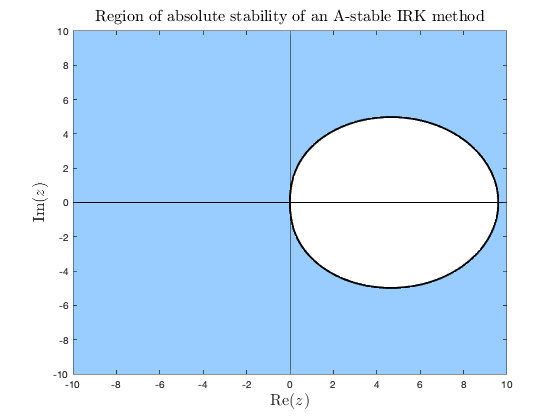

clear 

% Generate z values
x = linspace(-10, 10, 100);
y = linspace(-10, 10, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Define the stability function for the backwards Euler method
R = (1 + 1/3 * Z + 1/16 * Z .^ 2) ./ (1 - 2/3 * Z + 1/6 * Z.^2);

% Plot the region of absolute stability
contourf(X, Y, abs(R), [0 1], 'linewidth', 2)
hold on
plot([ -10, 10 ], [ 0, 0 ], 'k-')
plot([ 0, 0 ], [ -10, 10 ], 'k-')
hold off

xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
title('Region of absolute stability of an A-stable IRK method', ...
    'FontSize', 16, 'Interpreter', 'latex')
axis([ -10, 10, -10, 10 ])
colormap([ 153, 204, 255 ; 255, 255, 255 ] / 255)

## Stiffness

An important consideration when applying numerical methods to solve ODEs is whether the values that the step length can take for the method to be stable are large enough for the method to be applied without incurring prohibitive computational costs. For example, if a method requires a very small step length for it to be stabel, then the iterations required to step through the domain will be very large resulting in lots of computational operations and therefore time. Problems like is a known as stiff problems.

#### Definition (stiffness)

If a numerical method is forced to use, in a certain interval of integration, a step length which is excessively small in relation to the smoothness of the exact solution in that interval, then the problem is said to be **stiff** in that interval (Lambert, 1990). 

The stiffness of a problem depends on the system ODEs and the solver being applied to solve them and stiffness usually arises when there is a large variation in the behaviour of the individual ODEs in the system. Stiff systems require methods which are stable for larger values of the step length $h$, e.g., implicit or A-stable methods.

### Stiffness ratio

Consider a system of linear ODEs of the form 


$$\mathbf{y}' = A\mathbf{y},$$


where $A$ is a coefficient matrix. We use the test ODE $y'=\lambda y$ to examine the stability of a numerical method so we need to transform our system into this form. Let $u_i$ be a transformation of $y_i$ and $u_i' = \lambda_i u_i$ where $\lambda_i$ is an [eigenvalue](https://en.wikipedia.org/wiki/Eigenvalues_and_eigenvectors) of $A$ then 

$\pmatrix{ u_1' \cr u_2' \cr \vdots \cr u_N'} = 
\pmatrix{\lambda_1 \cr & \lambda_2 \cr & & \ddots \cr & & & \lambda_N} 
\pmatrix{u_1 \cr u_2 \cr \vdots \cr u_N}$.

Let $V = (\mathbf{v}_1, \mathbf{v}_2, \ldots, \mathbf{v}_N)$ be a matrix containing the [eigenvectors](https://en.wikipedia.org/wiki/Eigenvalues_and_eigenvectors) $\mathbf{v}_i$ corresponding to the eigenvalues $\lambda_i$ of $A$ then


$$AV = (A\mathbf{v}_1, A\mathbf{v}_2, \ldots, A\mathbf{v}_N),$$


and since $\lambda_i=A\mathbf{v}_i$


$$\quad \,\,\,\,AV = (\lambda_1 \mathbf{v}_1, \lambda_2 \mathbf{v}_2, \ldots, \lambda_N\mathbf{v}_N) = V\Lambda \\
V^{-1}AV = \Lambda.
$$


So $\Lambda = V^{-1}AV$ is a linear transformation that diagonalises $A$ and the stability behaviour of $\mathbf{y}' = A\mathbf{y}$ can be analysed by considering $\mathbf{y}' = \Lambda \mathbf{y}$. Since a stiff system will have a large variation in the step length and hence the values of $\lambda_i$ we can define a **stiffness ratio**


$$S = \frac{\max |\mathrm{Re}(\lambda_i)|}{\min |\mathrm{Re}(\lambda_i)|}.$$


#### Example 9

Determine the stiffness ratio of the following ODE


$$y'' - 1001y' - 1000y = 0.$$


Writing this as a system of first-order ODEs


$$y_1' = y_2',\\y_2' = 1001y_2 - 1000y_1,$$


which can be written as the matrix equation


$$\pmatrix{y_1'\cr y_2'} = \pmatrix{0&1\cr -1000 & 1001}\pmatrix{y_1 \cr y_2}.$$


The eigenvalues of the coefficient matrix are $\lambda_1=1$ and $\lambda_2 = 1000$ so


$$S = \frac{1000}{1} = 1000,$$


and this ODE can be considered stiff.

## Summary

- The local truncation error is the error at each step of a method due to the truncation of the Taylor series in deriving the method.

- The global truncation error is the accumulation of the local truncation errors.

- A method is considered absolutely stable if the local truncation errors do not increase from one step to the next.

- The stability of a method is analysed by considering the simple test ODE $y'=\lambda y$.

- The stability function of a method is the amount by which the solution to the test ODE changes over a single step of length.

- The region of absolute stability is the set of all values in the complex plane where the modulus of the stability function is less than or equal to 1 (i.e., the local truncation errors do not increase over a single step).

- The stability function for an explicit Runge-Kutta method is given in equation (4).

- The stability function for an order $k$ explicit Runge-Kutta method is the $k$th-order series expansion of $e^z$ given in equation (5).

- The stability function for an implicit Runge-Kutta method is given in equation (6).

- Implicit methods can be A-stable which means there is no limit placed on the value of the step length $h$ for a method to remain stable.

- A system of ODEs is considered stiff if the ratio of the eigenvalues of the coefficient matrix is large. Stiff systems require methods that have larger regions of absolute stability.

## Exercises

1.    Determine the stability function of the following Runge-Kutta method


$$\begin{array}{c|ccccc}
0 \\
\frac{1}{4} & \frac{1}{4} \\
\frac{1}{2} & \frac{1}{2} & 0 \\
\frac{3}{4} & \frac{1}{2} & \frac{1}{4} \\
0 & 0 & \frac{1}{6} & -\frac{1}{3} & \frac{1}{6} \\
& -1 & \frac{2}{3} & -\frac{1}{3} & \frac{2}{3} & 1
\end{array}$$


2.     Determine the stability function of the following Runge-Kutta method. Is this an A-stable method?


$$\begin{array}{c|cc}
\frac{1}{4} & \frac{7}{24} & -\frac{1}{24} \\
\frac{3}{4} & \frac{13}{24} & \frac{5}{24} \\ 
& \frac{1}{2} & \frac{1}{2}
\end{array}$$


3.     Plot the region of absolute stability for the following Runge-Kutta method.


$$\begin{array}{c|cc}
\frac{1}{3} & \frac{1}{3} & 0 \\
1 & 1 & 0 \\
& \frac{3}{4} & \frac{1}{4}
\end{array}$$


4.    Determine the stability function of the following Runge-Kutta method. What is the order of the method?


$$\begin{array}{c|ccccc}
0 \\
\frac{2}{7} & \frac{2}{7} \\
\frac{4}{7} & -\frac{8}{35} & \frac{4}{5} \\
\frac{6}{7} & \frac{29}{42} & -\frac{2}{3} & \frac{5}{6} \\
1 & \frac{1}{6} & \frac{1}{6} & \frac{5}{12} & \frac{1}{4} \\
& \frac{11}{96} & \frac{7}{24} & \frac{35}{96} & \frac{7}{48} & \frac{1}{12}
\end{array}$$


5.     Calculate the stiffness ratio for the following system of ODEs. 


$$y_1' = -80.6y_1 + 119.4y_2, \\ y_2' = 79.6y_1 - 120.4y_2.$$


        What are the maximum step lengths that the Euler method is stable for solving each equation?

## Functions

#### The Euler method

function [t, y] = euler(f, tspan, y0, h)

% Calculuates the solution to an IVP using the Euler method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, 1);
t(1) = tspan(1);
y(1) = y0;

% Solver loop
for n = 1 : nsteps
    y(n + 1) = y(n) + h * f(t(n), y(n));
    t(n + 1) = t(n) + h;
end

end

## References

Lambert, J.D. (1991) *Numerical Methods for Ordinary Differential Systems: The Initial Value Problem.* New York, NY, USA: John Wiley & Sons, Inc.